clear all
x = linspace(25,85,7);
f =[20 35 50 49 25 15 6]';
xbar = (x*f)/200;
var = ((x'-xbar).^2)'*f/200;


%%
%simulación de un número n de datos de la tabla
n=10000; %En la tabla son 20 pero aca lo cambiamos a 1000
n1=floor(0.1*n); %floor para que quede un número entero
n2=floor(0.175*n);
n3=floor(0.25*n);
n4=floor(0.245*n);
n5=floor(0.125*n);
n6=floor(0.075*n);
n7=floor(0.03*n);

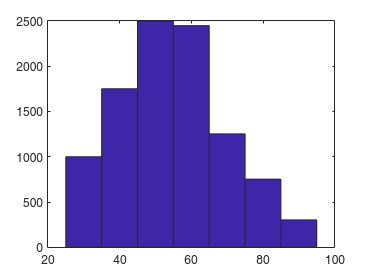

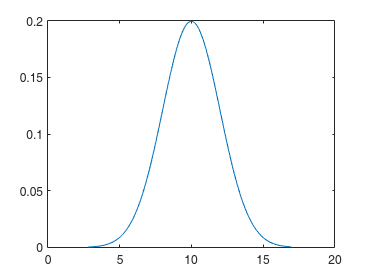


%%
%simular números aleatorios uniformes en el intervalo [a,b] es
%a+(b-a)*rand(n,1)
d1=25+10*rand(n1,1);
d2=35+10*rand(n2,1);
d3=45+10*rand(n3,1);
d4=55+10*rand(n4,1);
d5=65+10*rand(n5,1);
d6=75+10*rand(n6,1);
d7=85+10*rand(n7,1);
ds=[d1
    d2
    d3
    d4
    d5
    d6
    d7]; %datos simulados

media=mean(ds);
mediana=median(ds);
p30=prctile(ds,30);
p25=prctile(ds,25);
p75=prctile(ds,75);
hist(ds,7)

n = 1000

table =     0.1000    0.1000    0.1000    0.1000
    0.2000    0.2000    0.2000    0.2000
    0.3000    0.3000    0.3000    0.3000
    0.4000    0.4000    0.4000    0.4000
    0.5000    0.5000    0.5000    0.5000
    0.6000    0.6000    0.6000    0.6000
    0.7000    0.7000    0.7000    0.7000
    0.8000    0.8000    0.8000    0.8000
    0.9000    0.9000    0.9000    0.9000
    1.0000    1.0000    1.0000    1.0000


N = 5000

ans =    -0.4449    0.6623    0.8903   -0.3660
    0.2119    0.9284    1.8288    0.2725
    0.6959    1.1608    2.7752    0.6994
   -0.2691    0.7365    1.1009   -0.1879
    1.1406    1.3917    3.8763    1.0755
    0.3013    0.9862    2.0053    0.3582
    1.3237    1.4916    4.4518    1.2501
   -0.1026    0.7970    1.3088   -0.0540
   -0.7557    0.5280    0.5539   -0.7197
   -0.7680    0.5228    0.5470   -0.7364


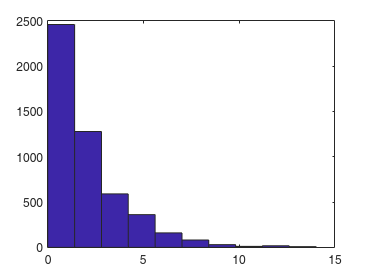

ans =     0.0218    0.8979    2.0461    0.0414


ans =     1.0497    0.4760    1.9807    1.0066


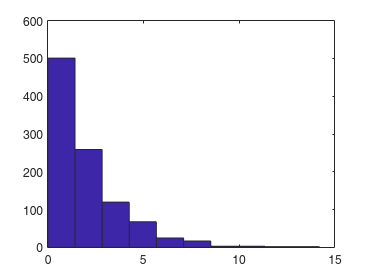

ans =    -0.0056    0.8844    1.9902    0.0154


ans =     1.0402    0.4677    1.9349    0.9983


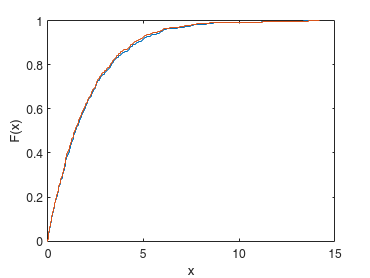

clear

n = 1000, K = 15;


%Simulacion de datos multivariantes con las mismas propiedades
X1 = [randn(n,1), wblrnd(1,2,n,1), exprnd(2,n,1), randn(n,1)];
%X1 = data(:,[1,2,3,4])

table1 = tabulate(X1(:,1));
table2 = tabulate(X1(:,2));
table3 = tabulate(X1(:,3));
table4 = tabulate(X1(:,4));

table = [cumsum(table1(:,3)) cumsum(table2(:,3)) cumsum(table3(:,3)) cumsum(table4(:,3))]

N = 5000

a = zeros(N,4);
for i=1:N
num = rand(1);

vars = [find(table(:,1)>(num*100),1,"first")
    find(table(:,2)>(num*100),1,"first")
    find(table(:,3)>(num*100),1,"first")
    find(table(:,4)>(num*100),1,"first")];

try
a1 = [table1(vars(1)-1), table1(vars(1))];
a2 = [table2(vars(2)-1), table2(vars(2))];
a3 = [table3(vars(3)-1), table3(vars(3))];
a4 = [table4(vars(4)-1), table4(vars(4))];
catch
a1 = [table1(vars(1)), table1(vars(1)+1)];
a2 = [table2(vars(2)), table2(vars(2)+1)];
a3 = [table3(vars(3)), table3(vars(3)+1)];
a4 = [table4(vars(4)), table4(vars(4)+1)];
end

a(i,:) = [unifrnd(a1(1), a1(2))
    unifrnd(a2(1), a2(2))
    unifrnd(a3(1), a3(2))
    unifrnd(a4(1), a4(2))]';
end

a(:,:)
clf

hist(a(:,3))
mean(a)
std(a)

hist(X1(:,3))
mean(X1)
std(X1)

clf
ecdf(a(:,3))
hold on
ecdf(X1(:,3))

x = data;
a = newData(data, 5000);

table =     0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0019
    0.0009    0.0019    0.0009    0.0009    0.0009    0.0009    0.0019    0.0009    0.0009    0.0019
    0.0009    0.0019    0.0019    0.0009    0.0009    0.0009    0.0028    0.0009    0.0009    0.0019
    0.0009    0.0019    0.0019    0.0009    0.0009    0.0009    0.0028    0.0009    0.0009    0.0028
    0.0009    0.0028    0.0028    0.0009    0.0009    0.0009    0.0028    0.0009    0.0009    0.0028
    0.0037    0.0037    0.0028    0.0009    0.0019    0.0009    0.0028    0.0019    0.0009    0.0028
    0.0037    0.0056    0.0028    0.0019    0.0028    0.0009    0.0028    0.0019    0.0009    0.0047
    0.0037    0.0066    0.0047    0.0028    0.0028    0.0019    0.0037    0.0019    0.0019    0.0056
    0.0037    0.0075    0.0047    0.0028    0.0047    0.0019    0.0037    0.0019    0.0019    0.0066
    0.0037    0.0094    0.0056    0.0028    0.0056    0.0028    0.0047    0.0019   

classes =   -24.6900  -34.8000  -29.8200  -29.8400  -33.8700  -21.5600  -30.2400  -34.0800  -33.0500  -30.0300
  -24.0360  -33.5268  -28.8531  -29.0752  -32.8993  -21.0074  -29.4323  -33.2888  -32.1999  -29.0436
  -23.3820  -32.2536  -27.8862  -28.3104  -31.9287  -20.4549  -28.6247  -32.4976  -31.3498  -28.0571
  -22.7280  -30.9803  -26.9193  -27.5457  -30.9580  -19.9023  -27.8170  -31.7063  -30.4997  -27.0707
  -22.0740  -29.7071  -25.9524  -26.7809  -29.9873  -19.3498  -27.0093  -30.9151  -29.6496  -26.0842
  -21.4200  -28.4339  -24.9856  -26.0161  -29.0167  -18.7972  -26.2017  -30.1239  -28.7994  -25.0978
  -20.7660  -27.1607  -24.0187  -25.2513  -28.0460  -18.2447  -25.3940  -29.3327  -27.9493  -24.1113
  -20.1120  -25.8874  -23.0518  -24.4866  -27.0753  -17.6921  -24.5863  -28.5414  -27.0992  -23.1249
  -19.4580  -24.6142  -22.0849  -23.7218  -26.1047  -17.1396  -23.7787  -27.7502  -26.2491  -22.1384
  -18.8040  -23.3410  -21.1180  -22.9570  -25.1340  -16.5870  -22.9710  -26.9590 

[dataSz vars] = size(a)

dataSz = 5000

vars = 10

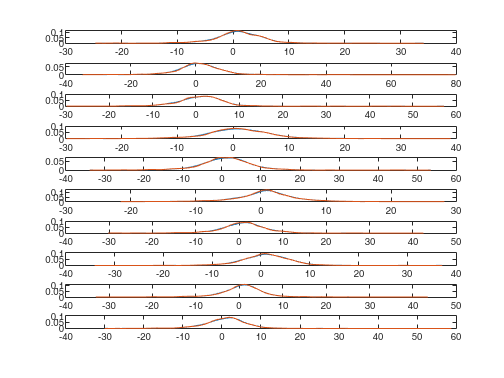

clf
for i =1:vars

    xi = x(:,i);
    

    ai = a(:,i);
    mini = min(min([xi; ai])); maxi = max(max([xi; ai]));
    pts = (mini:(maxi-mini)/100:maxi);
    [f1,x1] = ksdensity(xi,pts); 
    [f2,x2] = ksdensity(ai,pts); 
    dif = abs(f1-f2);

    at(i) = 1-trapz(pts,dif);
    subplot(vars,1,i)
    title(at(i))
    plot(x1,f1)
    hold on
    plot(x2,f2)
end

means = zeros(vars,3);
varis = zeros(vars,3);
for i =1:vars
xi = x(:,i);
means(i,1) = mean(xi);

x11 = a(:,i);
means(i,2) = mean(x11);

means(i,3) = abs(mean(xi)-mean(x11));


varis(i,1) = var(xi);

varis(i,2) = var(x11);

varis(i,3) = abs(var(xi)-var(x11));
end

means(:,3)'

ans =     0.0616    0.1242    0.0920    0.0838    0.1116    0.0600    0.0926    0.0820    0.0802    0.1279


varis(:,3)'

ans =     0.9428    5.2060    2.7762    1.5818    2.3301    0.7086    1.6945    1.8183    1.8386    3.3299


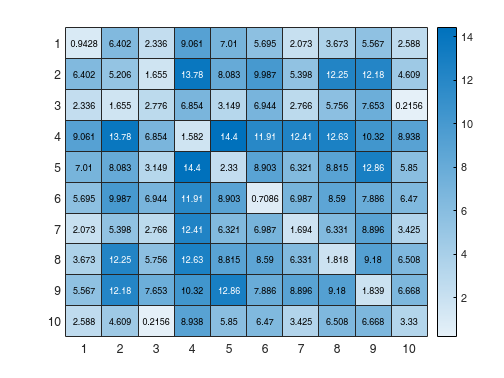

clf
heatmap(abs(cov(a)-cov(x)))

ddplot(x,data)